# Solving Blackjack with Q-Learning

## Overview

This example illustrates using reinforcement learning (RL), specifically Q-Learning, to learn a policy to play the casino card game blackjack.  The purpose of the example is to provide minimal working example to illustrate the implementation of a Q-learning strategy.

The MATLAB implementation is intentionally procedural and specific, limiting the use of objects and avoiding the Mathworks RL toolbox, to allow folks new to RL to experiment efficiently without the need to learn specific frameworks.

### Attribution

Adapted from the Farama Foundation's Gymnasium tutoral, [Solving Blackjack with Q-Learning](https://gymnasium.farama.org/tutorials/training_agents/blackjack_tutorial/): 

- The custom blackjack environmet is based on the Gymnasium [blackjack.py](https://github.com/Farama-Foundation/Gymnasium/blob/main/gymnasium/envs/toy_text/blackjack.py) environment, but is implementd as a standalone MATLAB class.

## Blackjack Environment

To formulate the problem appropriate for an RL approach the agent interacts with the game through the following interface:

- Action Space (Scalar, discrete values): stand (1) or hit (2).

- Observation Space (Vector of length 3, discrete):   `[player_sum, dealer_card, usable_ace]`   Where `player_sum` is the current total value of the player's hand from 4-21; `dealer_card` is the dealer's showing card value from 1-10; and usable ace describes whether the player holds a usable ace, 0-false or 1-true.

- Rewards: +1 for win, -1 for lose, 0 for draw, +1.5 for natural blackjack.

The MATLAB implementation is adapted from the Gymnasium [blackjack environment](https://gymnasium.farama.org/environments/toy_text/blackjack/).  Note that in this implementation the action space is 1, 2 to deal with MATLAB's array indexing.

## Setup environment

Make sure that the file **BlackJackEnv.m** is in MATLAB's path or the current working directory and instatiate the environment object.

env = BlackJackEnv(1);

The two main method of the environment are

- `reset()` which starts a new game and provides an initial observation of the state of the game.

- `step(action)` which takes an action and returns the next state of the game.

The optional argument is a logical to determine whether to give an additional reward (+1.5) starting with a natural blackjack, i.e. starting with an ace and ten (sum is 21).

## Starting a game and observing the environment

Get the initial state (observation) of a new game.  Recall that the observation is   `[player_sum, dealer_card, usable_ace]`  .

[initial_obs, info] = env.reset()

initial_obs =     20     2     1


info = struct with fields:
    episode_step: 0


## Executing an action

Random action within action space of {1, 2}.  1 for stand and 2 for hit.

Let's take a card, i.e., hit and exectute the action to see the results.

action = 2;
[next_obs, reward, terminated, truncated, info] = env.step(action)

next_obs =     17     2     0


reward = 0

terminated = logical
   0


truncated = logical
   0


info = struct with fields:
    episode_step: 1


Stand.  Did we win or loose?

action = 1;
[next_obs, reward, terminated, truncated, info] = env.step(action)

next_obs =     17     2     0


reward = 1

terminated = logical
   1


truncated = logical
   0


info = struct with fields:
    episode_step: 2
     dealer_hand: 0


## Create a Q-Table

A fundamental concept of the Q-learning approach is to store the mapping from state (observations) to actions in a table of state-action pairs: $Q(S,A)$.

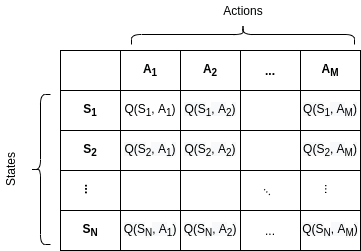

Use dictionary data type

- Keys are an array current observation: sum of players hand, dealer's face card and usable ace

- Values are 2x1 array with the index is the action and the elements are anticipated rewards.

function qtable = init_qtable()
    % Function to create a Q-Table with all zeros.
    qtable = dictionary();
    % Player sum
    for ps = 2:21

q =      0
     0


        % Dealer face card
        for df = 1:10
            % Usable ace
            for ua = 0:1
                observation = [ps, df, ua];
                qtable({observation}) = {zeros(2,1)};
            end
        end
    end
end

qtable = init_qtable()

Accessing a specific value in the Q-table dictionary is a two-step process

observation = [10, 1, 0];
qc = qtable({observation});
q = qc{1}

action = 1

## Adaptive Epsilon-Greedy Action Selection

We need to balance *exploration *(using the information we have gathered to maximize rewards) with *exploration* (gathering more information to imporove the policy).  Epsilon-Greedy is a simple method to balance exploration and exploitation by choosing between exploration and exploitation randomly. The epsilon-greedy, where epsilon refers to the probability of choosing to explore, exploits most of the time with a small chance of exploring.


$$A_t = \left\{ \matrix{\text{random action}   \:\:\:\: \text{with probabilty } \epsilon  \cr
\max_{A_t} Q(S_t,A)   \:\: \text{with probabilty } 1-\epsilon

}$$


A function to produce an action based on the current Q-Table, the current state of the game and the value of 

function action = get_action(qtable, observation , epsilon)
    if rand () < epsilon
        action = randi([1,2]);
    else
        qc = qtable({observation});
        [maxval, maxi] = max(qc{1});
        action = maxi;
    end
end

Test

observation = [10, 1, 0];
epsilon = 0.5;
action = get_action(qtable, observation, epsilon)

For this problem, we want to start with a bias towards exploration (high epsilon), but transition towards exploitation (low epsilon).  We can do this by adapting the value of epsilon as we train using a linear decay.


$$\epsilon_t = \epsilon_{\text{start}} - \frac{t}{T} (\epsilon_{\text{start}} - \epsilon_{\text{end}})$$


## Training Loop: Update Q-Table

- Q-learning is model-free, meaning it uses trial-and-error to explore the environment and learns the outcomes of the actions directly, without constructing an internal model.

- **It is a TD algorithm, where the predictions are reevaluated after taking a step.** Even incomplete episodes generate input for a TD algorithm. Overall, we measure how the last action is different from what we estimated initially, without waiting for a final outcome.

- **Q-learning is an off-policy algorithm.** It estimates the reward for state-action pairs based on the optimal (greedy) policy, independent of the agent’s actions. 

From: [https://www.baeldung.com/cs/epsilon-greedy-q-learning](https://www.baeldung.com/cs/epsilon-greedy-q-learning) 

In Q-learning, Q-values stored in the Q-table are partially updated using an estimate. Hence, there is no need to wait for the final reward and update prior state-action pair values in Q-learning.

To train the agent, we will let the agent play one episode (one complete game is called an episode) at a time and then update it’s Q-values after each episode. The agent will have to experience a lot of episodes to

explore the environment sufficiently.

- Learning Rate ($\alpha$): Controls how much weight is given to new information.  If $\alpha \approx 1$ more emphasis on new experience and Q-values updated more agressively for faster learning, but more suseptible to noise or errors in the reward signal.

-  Discount Factor ($\gamma$): The importance of future rewards.  High $\gamma$ means agent considers future rewards just as important as immediate rewards, maximizing total rewarts over time.   Low $\gamma$ means focus on immediat rewards, short-sited, greedy.  

#### Q-Function or Action-Value Function

The function approximates the value of selecting a certain action in a certain state. In this case,  is the action-value function learned by the algorithm.  The idea is to learn the optimal action-value function $Q^*$.

Value iteration update [https://en.wikipedia.org/wiki/Q-learning:](https://en.wikipedia.org/wiki/Q-learning:)


$$Q^{new}(S_{t},A_{t})\leftarrow (1-\underbrace {\alpha } _{\text{learning rate}})\cdot \underbrace {Q(S_{t},A_{t})} _{\text{current value}}+\underbrace {\alpha } _{\text{learning rate}}\cdot {\bigg (}\underbrace {\underbrace {R_{t+1}} _{\text{reward}}+\underbrace {\gamma } _{\text{discount factor}}\cdot \underbrace {\max _{a}Q(S_{t+1},a)} _{\text{estimate of optimal future value}}} _{\text{new value (temporal difference target)}}{\bigg )} $$


This is implemented in the code in a slightly different form:


$$Q^{new}(S_{t},A_{t})\leftarrow \underbrace {Q(S_{t},A_{t})} _{\text{current value}}+\underbrace {\alpha } _{\text{learning rate}}\cdot 
{\bigg (}\underbrace {\underbrace {R_{t+1}} _{\text{reward}}+\underbrace {\gamma } _{\text{discount factor}}\cdot \underbrace {\max _{a}Q(S_{t+1},a)} _{\text{estimate of optimal future value}} - \underbrace {Q(S_{t},A_{t})} _{\text{current value}} } _{\text{temporal difference}}{\bigg )} $$


function [qtable, temporal_difference] = update(qtable, observation, action, reward, terminated, next_observation, discount_factor, learning_rate)
    future_q_value = 0;
    if ~terminated
        qc = qtable({next_observation});
        future_q_value = max(qc{1});
    end
    qc = qtable({observation});
    qval = qc{1};
    temporal_difference = reward + discount_factor * future_q_value - qval(action);
    qvals_cell = qtable({observation});
    new_qvals = qvals_cell{1};
    new_qvals(action) = new_qvals(action) + learning_rate * temporal_difference;
    qtable({observation}) = {new_qvals};
end


Test our update function.

learning_rate = 0.01;
discount_factor = 0.95;
n_episodes = 10;
start_epsilon = 1.0;
epsilon_decay = start_epsilon / (n_episodes / 2);  %reduce the exploration over time
final_epsilon = 0.1;

observation = [10, 1, 0];
action = 1;
reward = 1;
terminated = 0;
next_observation = [15, 1, 0];
[qtable, temporal_difference] = update(qtable, observation, action, reward, terminated, next_observation, discount_factor, learning_rate);

 

## Training

Now we are ready to train our Q-Learning RL model by having it explore and exploit the game environemnt.

Re-initialize Q-Table

qtable = init_qtable();

#### Specify *hyperparameters*

We specify these as a structure so that we can keep them together and it makes it eaiser to save the results.

Info: The current hyperparameters are set to quickly train a decent agent. If you want to converge to the optimal policy, try increasing the n_episodes by 10x and lower the learning_rate (e.g. to 0.001).  But, be careful, training can be computationally demanding.

hyperparams.learning_rate = 0.01;
hyperparams.discount_factor = 0.95;
hyperparams.n_episodes = 100000;
hyperparams.start_epsilon = 1.0;
hyperparams.epsilon_decay = start_epsilon / (n_episodes / 2);  % reduce the exploration over time
hyperparams.final_epsilon = 1.0;

Run N training episodes

% Allocate storage 
rewards = zeros(1, hyperparams.n_episodes);
training_error = zeros(1, hyperparams.n_episodes);
episode_length = zeros(1, hyperparams.n_episodes);

% Starting greediness value
epsilon = hyperparams.start_epsilon;

for ii = 1:hyperparams.n_episodes
    [obs, info] = env.reset();
    terminated = false;
    % Play one episode
    while ~terminated
        action = get_action(qtable, obs , epsilon);
        [next_obs, reward, terminated, truncated, info] = env.step(action);
        % Update the agent / q-table
        [qtable, temporal_difference] = update(qtable, obs, action, reward, terminated, next_obs, hyperparams.discount_factor, hyperparams.learning_rate);

        % Update the current obs
        obs = next_obs;
    end
    rewards(ii) = reward;
    training_error(ii) = temporal_difference;
    episode_length(ii) = info.episode_step;

    % Epsilon decay
    epsilon = max(hyperparams.final_epsilon, epsilon - hyperparams.epsilon_decay);
end

## Visualize the training

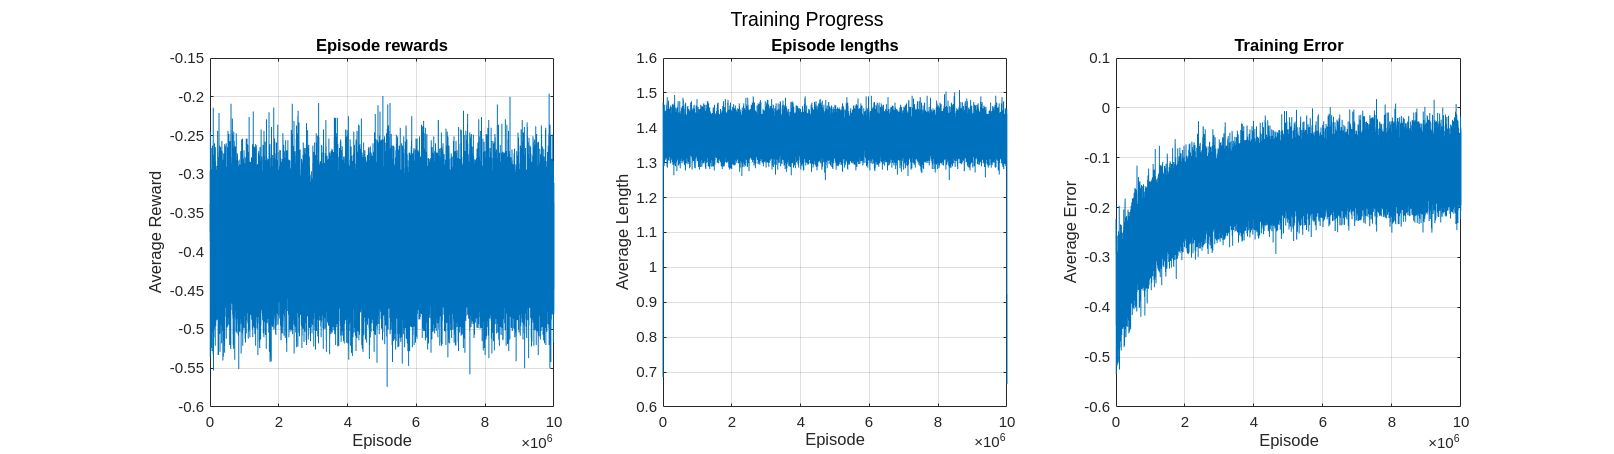


figure;
clf;

% Episode rewards plot
rolling_length = 500;
subplot(1, 3, 1);
reward_moving_average = conv(rewards, ones(rolling_length,1), 'valid') / rolling_length;
plot(1:length(reward_moving_average), reward_moving_average);
title('Episode rewards');
xlabel('Episode');
ylabel('Average Reward');
grid on;
% Episode lengths plot
subplot(1, 3, 2);
length_data = episode_length;
length_moving_average = conv(length_data, ones(rolling_length,1), 'same') / rolling_length;
plot(1:length(length_moving_average), length_moving_average);
title('Episode lengths');
xlabel('Episode');
ylabel('Average Length');
grid on;

% Training error plot
subplot(1, 3, 3);
error_data = training_error;
training_error_moving_average = conv(error_data, ones(rolling_length,1), 'same') / rolling_length;
plot(1:length(training_error_moving_average), training_error_moving_average);
title('Training Error');
xlabel('Episode');
ylabel('Average Error');
grid on;

% Adjust layout
sgtitle('Training Progress');  % Optional overall title
set(gcf, 'Color', 'white');  % White background

% Adjust spacing between subplots
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);
set(findall(gcf, 'Type', 'Axes'), 'FontSize', 10);

## Visualize the policy

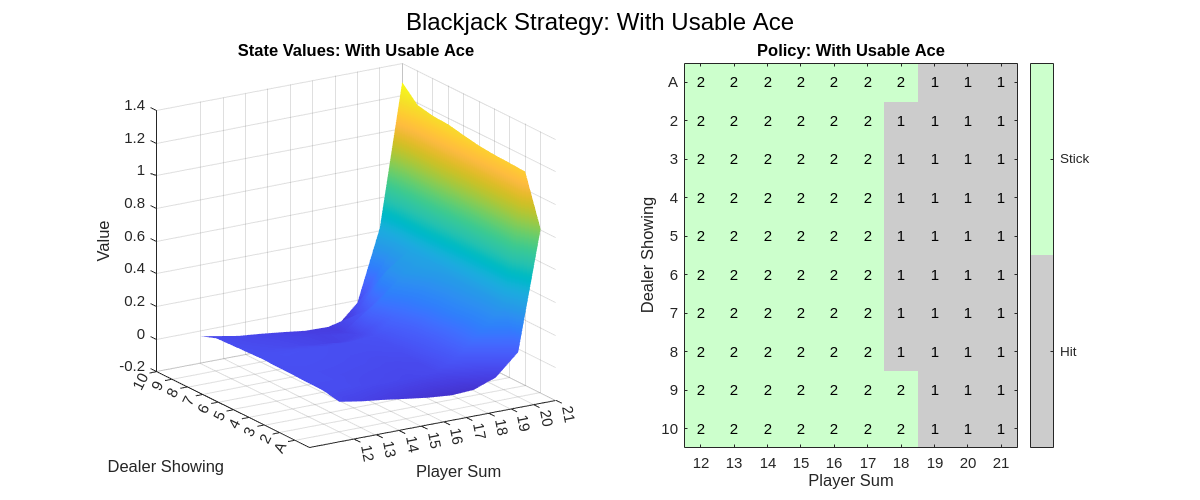

function [value_grid, policy_grid] = create_blackjack_plots(qtable, usable_ace)

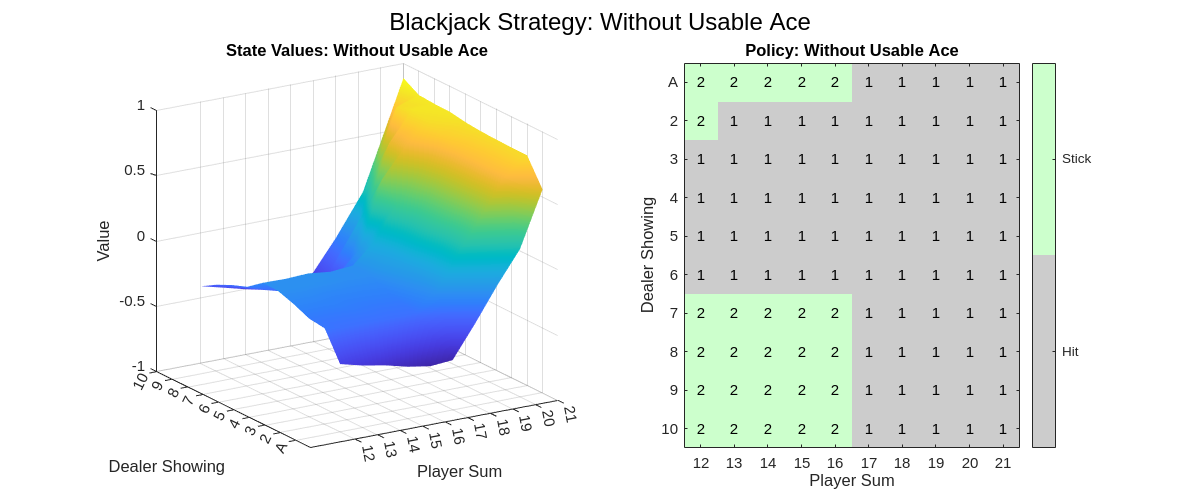

    % Create value and policy grids and plot them

    
    % Create meshgrid for player and dealer counts
    [player_count, dealer_count] = meshgrid(12:21, 1:10);
    
    % Initialize value and policy grids
    value = zeros(size(player_count));
    policy = zeros(size(player_count));
    
    % Fill in the grids
    for i = 1:size(player_count, 1)
        for j = 1:size(player_count, 2)
            state = [player_count(i,j), dealer_count(i,j), usable_ace];
            q_values = qtable({state});
            [max_value, max_action] = max(q_values{1});
            value(i,j) = max_value;
            policy(i,j) = max_action;
        end
    end
    
    % Create figure with subplots
    figure('Position', [100 100 1200 500]);
    
    % Plot state values (3D surface)
    subplot(1, 2, 1);
    surf(player_count, dealer_count, value);
    colormap(gca);
    shading interp;
    
    % Adjust 3D view
    view(-32, 19);
    
    % Labels and title
    if usable_ace
        title_text = 'With Usable Ace';
    else
        title_text = 'Without Usable Ace';
    end
    title(['State Values: ' title_text]);
    xlabel('Player Sum');
    ylabel('Dealer Showing');
    zlabel('Value');
    
    % Adjust axes
    xticks(12:21);
    yticks(1:10);
    yticklabels({'A', '2', '3', '4', '5', '6', '7', '8', '9', '10'});
    
    % Plot policy (heatmap)
    subplot(1, 2, 2);
    imagesc(12:21, 1:10, policy);
    colormap(gca, [0.8 0.8 0.8; 0.8 1 0.8]); % Light green for hit, grey for stick
    
    % Add grid to policy plot
    % grid on;
    % set(gca, 'GridAlpha', 0.3, 'Layer', 'top');
    
    % Labels and title
    title(['Policy: ' title_text]);
    xlabel('Player Sum');
    ylabel('Dealer Showing');
    
    % Adjust axes
    yticks(1:10);
    yticklabels({'A', '2', '3', '4', '5', '6', '7', '8', '9', '10'});
    xticks(12:21);
    
    % Add colorbar with custom labels
    c = colorbar;
    c.Ticks = [1.25 1.75];
    c.TickLabels = {'Hit', 'Stick'};
    
    % Add value annotations to policy plot
    hold on;
    for i = 1:size(policy, 1)
        for j = 1:size(policy, 2)
            text(j+11, i, num2str(policy(i,j)), ...
                'HorizontalAlignment', 'center', ...
                'Color', 'black');
        end
    end
    hold off;
    
    % Adjust overall figure appearance
    sgtitle(['Blackjack Strategy: ' title_text], 'FontSize', 16);
    set(gcf, 'Color', 'white');
    
    % Return grids if needed
    value_grid = {player_count, dealer_count, value};
    policy_grid = policy;
end

[value_grid, policy_grid] = create_blackjack_plots(qtable, 1);
[value_grid, policy_grid] = create_blackjack_plots(qtable, 0);

## Save the results

Because it can take significant compute to do the training, we want to save the results as a .mat file for later

%save("blackjack_qlearning_default.mat", "qtable", "hyperparams")